clear
N = 180;
gen_nodes1 = [0,0;0,0.04;0.2,0.04;0.2,0];
[Ele_Nodes1,Nodes1,posNode1,A1,Total1] = nodeCoordinates(gen_nodes1,N);

el_sidex = 0.0067

%{
figure
for ele = 1:Total
    plot(Ele_Nodes1(:,ele*2-1),Ele_Nodes1(:,ele*2),'b-')
    %text(Ele_Nodes1(1,ele*2-1),Ele_Nodes1(1,ele*2),num2str(ele))
    hold on
end
%}

gen_nodes2 = [0.08,0.04;0.08,0.1;0.1,0.120;0.120,0.04];
[Ele_Nodes2,Nodes2,posNode2,A2,Total2] = nodeCoordinates(gen_nodes2,ceil(N/3.333333));

el_sidex = 0.0067

%{
for ele = 1:Total2
    plot(Ele_Nodes2(:,ele*2-1),Ele_Nodes2(:,ele*2),'b-')
    %text(Ele_Nodes2(1,ele*2-1),Ele_Nodes2(1,ele*2),num2str(ele))
    hold on
end
xlim([0,0.3])
ylim([0,0.3])
%}
Element_total = [Ele_Nodes1,Ele_Nodes2];
figure
T_final = Total1+Total2

T_final = 246

%{
for ele = 1:T_final
    plot(Element_total(:,ele*2-1),Element_total(:,ele*2),'b-')
    text(Element_total(1,ele*2-1),Element_total(1,ele*2),num2str(ele))
    hold on
end


figure
for ele = 1:Total1
    plot(Ele_Nodes1(:,ele*2-1),Ele_Nodes1(:,ele*2),'b-')
    %text(Ele_Nodes1(1,ele*2-1),Ele_Nodes1(1,ele*2),num2str(ele))
    hold on
end
NNN = Nodes1';
NNN = NNN(:);
NNN = NNN';
for ele = 1:size(Nodes1,1)
    %plot(Ele_Nodes1(:,ele*2-1),Ele_Nodes1(:,ele*2),'b-')
    text(NNN(1,ele*2-1),NNN(1,ele*2),num2str(ele))
    hold on
end

figure
for ele = 1:Total2
    plot(Ele_Nodes2(:,ele*2-1),Ele_Nodes2(:,ele*2),'b-')
    %text(Ele_Nodes1(1,ele*2-1),Ele_Nodes1(1,ele*2),num2str(ele))
    hold on
end
NNN = Nodes2';
NNN = NNN(:);
NNN = NNN';
for ele = 1:size(Nodes2,1)
    %plot(Ele_Nodes1(:,ele*2-1),Ele_Nodes1(:,ele*2),'b-')
    text(NNN(1,ele*2-1),NNN(1,ele*2),num2str(ele))
    hold on
end

%}
test = A1+1

test = 31

test2 = A2+1

test2 = 7

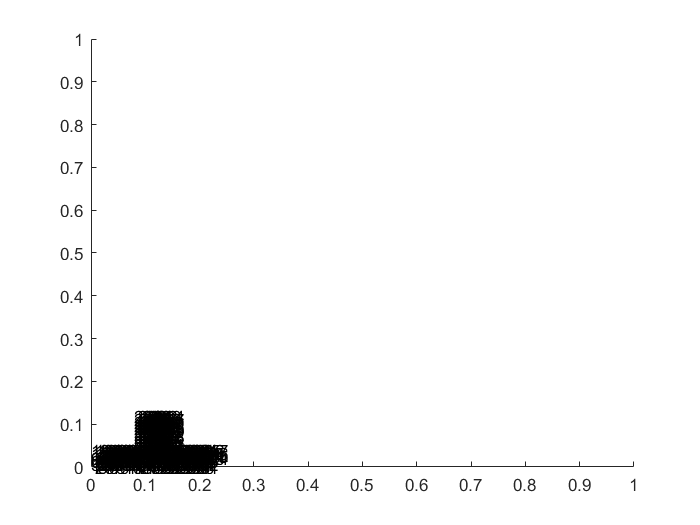

Nodes2(1:test2,:) = [];
test3 = [Nodes1;Nodes2];
figure
NNN = test3';
NNN = NNN(:);
NNN = NNN';
for ele = 1:size(test3,1)
    %plot(Ele_Nodes1(:,ele*2-1),Ele_Nodes1(:,ele*2),'b-')
    text(NNN(1,ele*2-1),NNN(1,ele*2),num2str(ele))
    hold on
end

test4 = posNode2+size(Nodes1,1)-test2

test4 =    211   212   219   218
   212   213   220   219
   213   214   221   220
   214   215   222   221
   215   216   223   222
   216   217   224   223
   218   219   226   225
   219   220   227   226
   220   221   228   227
   221   222   229   228


%
if rem(A1,2) == 0
    test4(1:A2,1:2) = test4(1:A2,1:2)-ceil(test/4)-test2+1
else
    test4(1:A2,1:2) = test4(1:A2,1:2)-ceil(test/4)-test2+1
end

test4 =    197   198   219   218
   198   199   220   219
   199   200   221   220
   200   201   222   221
   201   202   223   222
   202   203   224   223
   218   219   226   225
   219   220   227   226
   220   221   228   227
   221   222   229   228


%
test5 = [posNode1;test4];

for i = 1:Total1+Total2
    
    Ele_Nodes(1:4,i*2-1:i*2) = test3(test5(i,:),:);
    
end

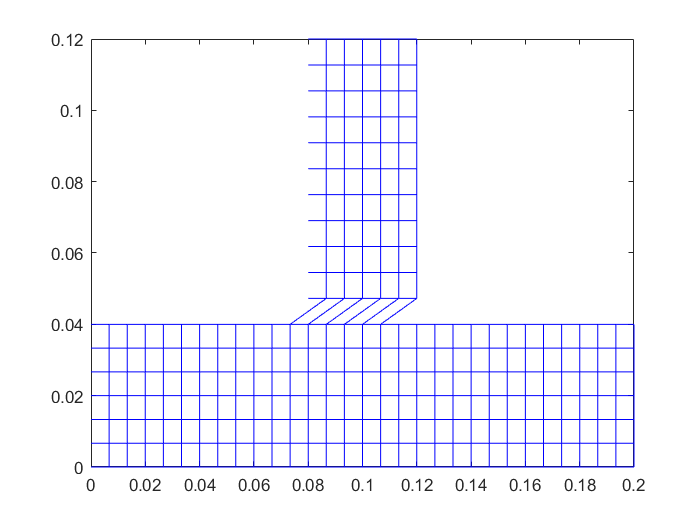


figure
for ele = 1:Total1+Total2
    plot(Ele_Nodes(:,ele*2-1),Ele_Nodes(:,ele*2),'b-')
    %text(Ele_Nodes(1,ele*2-1),Ele_Nodes(1,ele*2),num2str(ele))
    hold on
end